% MATH 515
% Problem Set 5
% Andrew Hutsell

% Problem 2

% Part a
function optimal_rk2_errors = optimal_rk2
    % RHS of ODE
    f = @(t,y) (4*t .* sqrt(1 + y.^2)) ./ y;
    % exact solution
    y_exact = @(t) sqrt((2*t.^2 + sqrt(2)).^2 - 1);
    T = 5;
    hs = [1/16, 1/32, 1/64, 1/128, 1/256];
    optimal_rk2_errors = zeros(size(hs));
    for k = 1:length(hs)
        h = hs(k);
        N = round(T / h);
        t = 0;
        w = 1;
        for n = 1:N
            k1 = f(t, w);
            k2 = f(t + (3/4)*h, w + (3/4)*h*k1);
            w = w + (h/3)*(k1 + 2*k2);
            t = t + h;
        end
        optimal_rk2_errors(k) = abs(w - y_exact(T));
    end
    % Compute order
    order = log(optimal_rk2_errors(1:end-1)./optimal_rk2_errors(2:end)) ./ log(hs(1:end-1)./hs(2:end));
    fprintf('\nOptimal RK2 Order:\n');
    disp(order);
end


% Part b
function twostep_adams_bashforth_errors = twostep_adams_bashforth
    % RHS of ODE
    f = @(t,y) (4*t .* sqrt(1 + y.^2)) ./ y;
    % Exact solution
    y_exact = @(t) sqrt((2*t.^2 + sqrt(2)).^2 - 1);
    T = 5;
    hs = [1/16, 1/32, 1/64, 1/128, 1/256];
    twostep_adams_bashforth_errors = zeros(size(hs));
    for k = 1:length(hs)
        h = hs(k);
        N = round(T / h);
        t = zeros(1, N+1);
        w = zeros(1, N+1);
        t(1) = 0;
        w(1) = 1;
        k1 = f(t(1), w(1));
        k2 = f(t(1) + (3/4)*h, w(1) + (3/4)*h*k1);
        w(2) = w(1) + (h/3)*(k1 + 2*k2);
        t(2) = h;
        for n = 2:N
            t(n+1) = t(n) + h;
            w(n+1) = w(n) + (h/2)*(3*f(t(n), w(n)) - f(t(n-1), w(n-1)) );
        end
        twostep_adams_bashforth_errors(k) = abs(w(end) - y_exact(T));
    end

    % Compute order
    order = log(twostep_adams_bashforth_errors(1:end-1)./twostep_adams_bashforth_errors(2:end)) ./ log(hs(1:end-1)./hs(2:end));
    fprintf('\nTwo-Step Adams-Bashforth Order:\n');
    disp(order);
end

% Part c
function onestep_adams_moulton_errors = onestep_adams_moulton
    % RHS of ODE
    f = @(t,y) (4*t .* sqrt(1 + y.^2)) ./ y;
    % exact solution
    y_exact = @(t) sqrt((2*t.^2 + sqrt(2)).^2 - 1);
    T = 5;
    hs = [1/16, 1/32, 1/64, 1/128, 1/256];
    onestep_adams_moulton_errors = zeros(size(hs));
    for k = 1:length(hs)
        h = hs(k);
        N = round(T / h);
        t = zeros(1, N+1);
        w = zeros(1, N+1);
        t(1) = 0;
        w(1) = 1;
        for n = 1:N
            t(n+1) = t(n) + h;
            fn = f(t(n), w(n));
            w_new = w(n) + h * fn;
            for iter = 1:10
                w_new = w(n) + (h/2) * (fn + f(t(n+1), w_new) );
            end
            w(n+1) = w_new;
        end
        onestep_adams_moulton_errors(k) = abs(w(end) - y_exact(T));
    end

    % observed order
    order = log(onestep_adams_moulton_errors(1:end-1)./onestep_adams_moulton_errors(2:end)) ./ log(hs(1:end-1)./hs(2:end));
    fprintf('\nOne-Step Adams-Moulton Order:\n');
    disp(order);
end

% Part d
function heun_errors = heun
    % RHS of ODE
    f = @(t,y) (4*t .* sqrt(1 + y.^2)) ./ y;
    % exact solution
    y_exact = @(t) sqrt((2*t.^2 + sqrt(2)).^2 - 1);
    T = 5;
    hs = [1/16, 1/32, 1/64, 1/128, 1/256];
    heun_errors = zeros(size(hs));
    for k = 1:length(hs)
        h = hs(k);
        N = round(T / h);
        t = zeros(1, N+1);
        w = zeros(1, N+1);
        t(1) = 0;
        w(1) = 1;
        for n = 1:N
            t(n+1) = t(n) + h;
            w_hat = w(n) + h * f(t(n), w(n));
            w(n+1) = w(n) + (h/2) * (f(t(n), w(n)) + f(t(n+1), w_hat));
        end
        heun_errors(k) = abs(w(end) - y_exact(T));
    end

    % observed order
    order = log(heun_errors(1:end-1)./heun_errors(2:end)) ./ log(hs(1:end-1)./hs(2:end));
    fprintf('\nHeun Order:\n');
    disp(order);
end

hs = [1/16, 1/32, 1/64, 1/128, 1/256];
optimal_rk2_errors = optimal_rk2;


Optimal RK2 Order:
    2.0196    2.0085    2.0040    2.0019



twostep_adams_bashforth_errors = twostep_adams_bashforth;


Two-Step Adams-Bashforth Order:
    2.0141    2.0069    2.0034    2.0017



onestep_adams_moulton_errors = onestep_adams_moulton;


One-Step Adams-Moulton Order:
    2.0018    2.0005    2.0001    2.0000



heun_errors = heun;


Heun Order:
    2.0232    2.0100    2.0046    2.0022



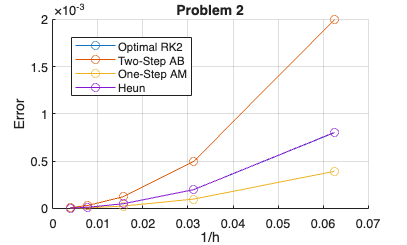


% log-log plot
figure;
hold on
loglog(hs, optimal_rk2_errors, 'o-', 'DisplayName', 'Optimal RK2');
loglog(hs, twostep_adams_bashforth_errors, 'o-', 'DisplayName', 'Two-Step AB');
loglog(hs, onestep_adams_moulton_errors, 'o-', 'DisplayName', 'One-Step AM');
loglog(hs, heun_errors, 'o-', 'DisplayName', 'Heun');
xlabel('1/h');
ylabel('Error');
title('Problem 2');
legend('Location','best');
grid on;
hold off

% Problem 4

% For this problem, I made a singular function to cover all solvers and time
% steps that were used.

function [x,y_var,z,t] = lorenz_solver(y0, solver, h)
    % Lorenz system parameters
    sigma = 10;
    r = 28;
    b = 8/3;
    
    % Time span with step h = 0.001
    h = 0.001;
    tspan = 0:h:10;
    
    % Initial condition
    y0 = y0;
    
    % Define Lorenz system
    lorenz = @(t, y) [sigma * (y(2) - y(1)); r * y(1) - y(2) - y(1)*y(3); y(1)*y(2) - b * y(3)];
    
    if solver == 45
        [t, y] = ode45(lorenz, tspan, y0);
    elseif solver == 113
        [t, y] = ode113(lorenz, tspan, y0);
    elseif solver == 15
        [t, y] = ode15s(lorenz, tspan, y0);
    elseif solver == 23
        [t, y] = ode23(lorenz, tspan, y0);
    end
    
    % Extract variables
    x = y(:,1);
    y_var = y(:,2);
    z = y(:,3);
end

% Part a
y0_a = [5; 5; 5];
h = 0.001;
solver = 45

solver = 45

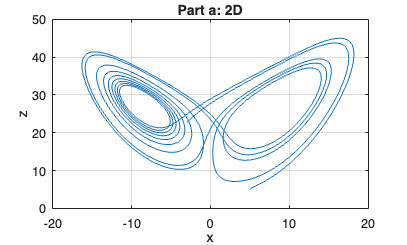

[x_a,y_var_a,z_a,t] = lorenz_solver(y0_a, solver, h);

% 2D Plot
figure;
plot(x_a, z_a);
xlabel('x');
ylabel('z');
title('Part a: 2D');
grid on;

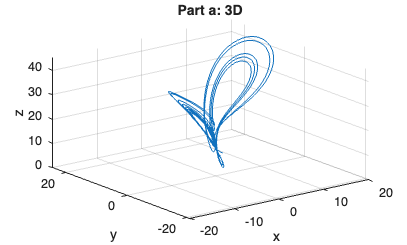


% 3D Plot
figure;
plot3(x_a, y_var_a, z_a);
xlabel('x');
ylabel('y');
zlabel('z');
title('Part a: 3D');
grid on;
view(3);


% Part b
y0_b = [5 + 1e-5; 5 + 1e-5; 5 + 1e-5];
solver = 45

solver = 45

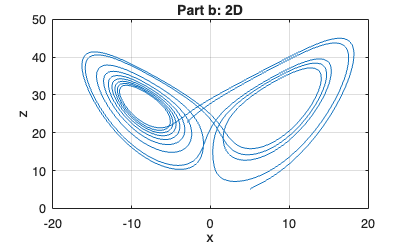

[x_b,y_var_b,z_b,t] = lorenz_solver(y0_b, solver, h);

% 2D Plot
figure;
plot(x_b, z_b);
xlabel('x');
ylabel('z');
title('Part b: 2D');
grid on;

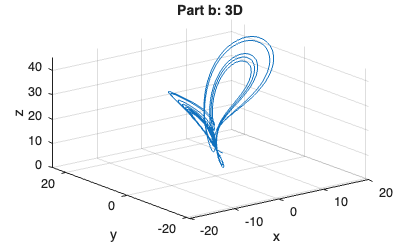


% 3D Plot
figure;
plot3(x_b, y_var_b, z_b);
xlabel('x');
ylabel('y');
zlabel('z');
title('Part b: 3D');
grid on;
view(3);

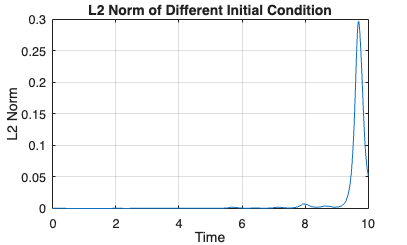


% Part c
% Compute L2 norm
diff_norm = sqrt( (x_a - x_b).^2 + (y_var_a - y_var_b).^2 + (z_a - z_b).^2 );

% Plot L2 norm
figure;
plot(t, diff_norm);
xlabel('Time');
ylabel('L2 Norm');
title('L2 Norm of Different Initial Condition');
grid on;




% Part d

y0_a = [5; 5; 5];
y0_b = [5 + 1e-5; 5 + 1e-5; 5 + 1e-5];

% ode113
solver = 113

solver = 113

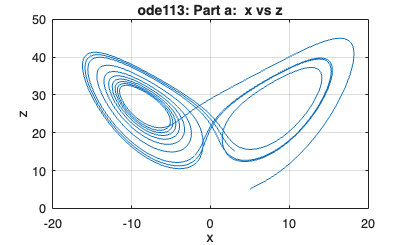

[x_ode113_a,y_var_ode113_a,z_ode113_a,t] = lorenz_solver(y0_a, solver, h);
[x_ode113_b,y_var_ode113_b,z_ode113_b,t] = lorenz_solver(y0_b, solver, h);

% Part a
figure;
plot(x_ode113_a, z_ode113_a);
xlabel('x');
ylabel('z');
title('ode113: Part a:  x vs z');
grid on;

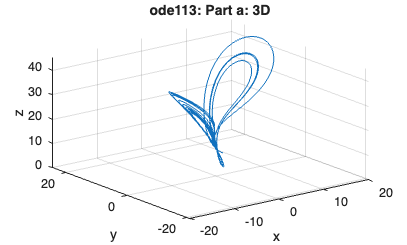


% 3D Plot
figure;
plot3(x_ode113_a, y_var_ode113_a, z_ode113_a);
xlabel('x');
ylabel('y');
zlabel('z');
title('ode113: Part a: 3D');
grid on;
view(3);

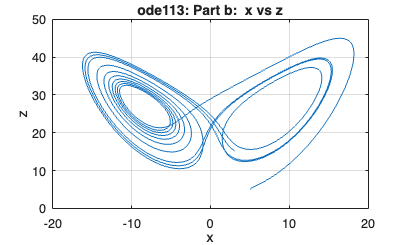


% Part b
% 2D Plot
figure;
plot(x_ode113_b, z_ode113_b);
xlabel('x');
ylabel('z');
title('ode113: Part b:  x vs z');
grid on;

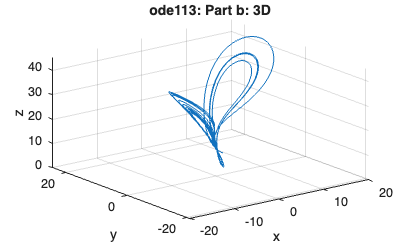


% 3D Plot
figure;
plot3(x_ode113_b, y_var_ode113_b, z_ode113_b);
xlabel('x');
ylabel('y');
zlabel('z');
title('ode113: Part b: 3D');
grid on;
view(3);

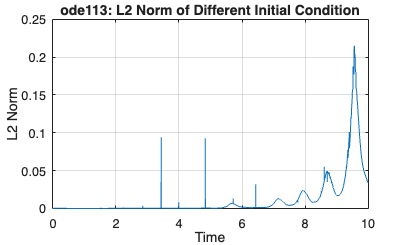


% Part c
% Compute L2 norm
diff_norm_ode113 = sqrt((x_ode113_a - x_ode113_b).^2 + (y_var_ode113_a - y_var_ode113_b).^2 + (z_ode113_a - z_ode113_b).^2 );

% Plot L2 norm
figure;
plot(t, diff_norm_ode113);
xlabel('Time');
ylabel('L2 Norm');
title('ode113: L2 Norm of Different Initial Condition');
grid on;




% ode15
solver = 15

solver = 15

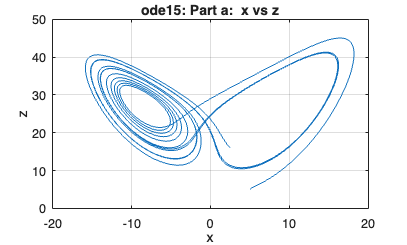

[x_ode15_a,y_var_ode15_a,z_ode15_a,t] = lorenz_solver(y0_a, solver, h);
[x_ode15_b,y_var_ode15_b,z_ode15_b,t] = lorenz_solver(y0_b, solver, h);

% Part a
figure;
plot(x_ode15_a, z_ode15_a);
xlabel('x');
ylabel('z');
title('ode15: Part a:  x vs z');
grid on;

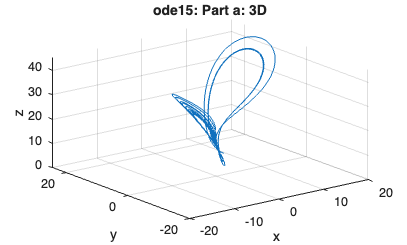


% 3D Plot
figure;
plot3(x_ode15_a, y_var_ode15_a, z_ode15_a);
xlabel('x');
ylabel('y');
zlabel('z');
title('ode15: Part a: 3D');
grid on;
view(3);

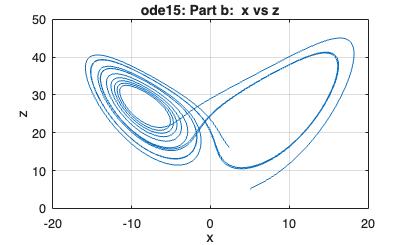


% Part b
% 2D Plot
figure;
plot(x_ode15_b, z_ode15_b);
xlabel('x');
ylabel('z');
title('ode15: Part b:  x vs z');
grid on;

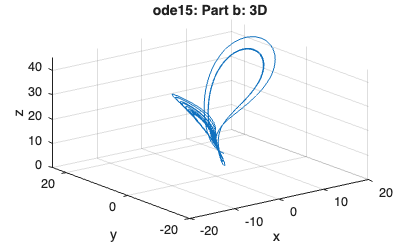


% 3D Plot
figure;
plot3(x_ode15_b, y_var_ode15_b, z_ode15_b);
xlabel('x');
ylabel('y');
zlabel('z');
title('ode15: Part b: 3D');
grid on;
view(3);

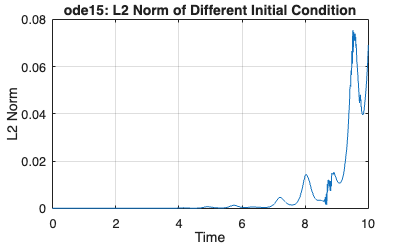


% Part c
% Compute L2 norm
diff_norm_ode15 = sqrt((x_ode15_a - x_ode15_b).^2 + (y_var_ode15_a - y_var_ode15_b).^2 + (z_ode15_a - z_ode15_b).^2 );

% Plot L2 norm
figure;
plot(t, diff_norm_ode15);
xlabel('Time');
ylabel('L2 Norm');
title('ode15: L2 Norm of Different Initial Condition');
grid on;




% ode23
solver = 23

solver = 23

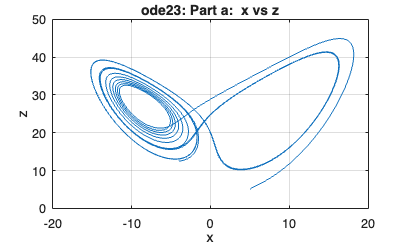

[x_ode23_a,y_var_ode23_a,z_ode23_a,t] = lorenz_solver(y0_a, solver, h);
[x_ode23_b,y_var_ode23_b,z_ode23_b,t] = lorenz_solver(y0_b, solver, h);

% Part a
figure;
plot(x_ode23_a, z_ode23_a);
xlabel('x');
ylabel('z');
title('ode23: Part a:  x vs z');
grid on;

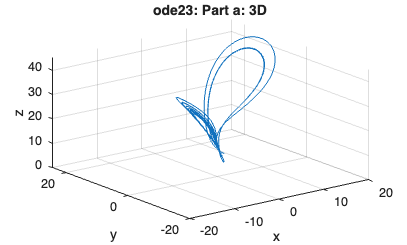


% 3D Plot
figure;
plot3(x_ode23_a, y_var_ode23_a, z_ode23_a);
xlabel('x');
ylabel('y');
zlabel('z');
title('ode23: Part a: 3D');
grid on;
view(3);

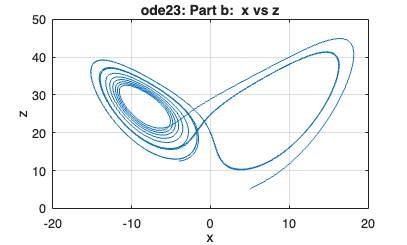


% Part b
% 2D Plot
figure;
plot(x_ode23_b, z_ode23_b);
xlabel('x');
ylabel('z');
title('ode23: Part b:  x vs z');
grid on;

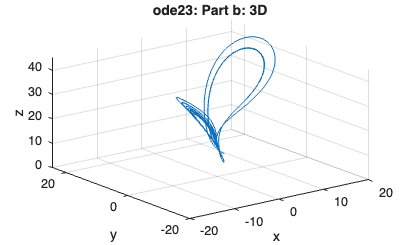


% 3D Plot
figure;
plot3(x_ode23_b, y_var_ode23_b, z_ode23_b);
xlabel('x');
ylabel('y');
zlabel('z');
title('ode23: Part b: 3D');
grid on;
view(3);

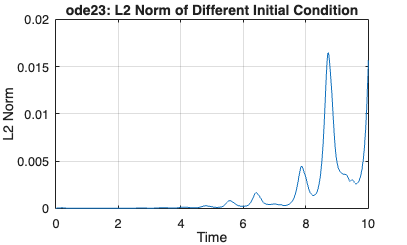


% Part c
% Compute L2 norm
diff_norm_ode23 = sqrt((x_ode23_a - x_ode23_b).^2 + (y_var_ode23_a - y_var_ode23_b).^2 + (z_ode23_a - z_ode23_b).^2 );

% Plot L2 norm
figure;
plot(t, diff_norm_ode23);
xlabel('Time');
ylabel('L2 Norm');
title('ode23: L2 Norm of Different Initial Condition');
grid on;




% Change time steps with same solver (ode45)
% h=1
solver = 45

solver = 45

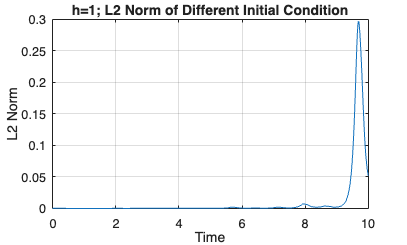

h = 1;
[x_ode45_a,y_var_ode45_a,z_ode45_a,t] = lorenz_solver(y0_a, solver, h);
[x_ode45_b,y_var_ode45_b,z_ode45_b,t] = lorenz_solver(y0_b, solver, h);

% Compute L2 norm
diff_norm_ode45 = sqrt((x_ode45_a - x_ode45_b).^2 + (y_var_ode45_a - y_var_ode45_b).^2 + (z_ode45_a - z_ode45_b).^2 );

% Plot L2 norm
figure;
plot(t, diff_norm_ode45);
xlabel('Time');
ylabel('L2 Norm');
title('h=1; L2 Norm of Different Initial Condition');
grid on;



% h=0.1
solver = 45

solver = 45

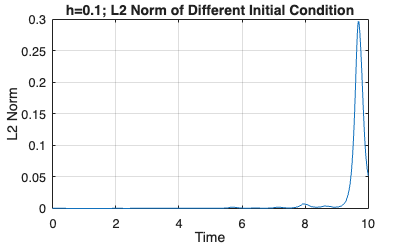

h = 0.1;
[x_ode45_a,y_var_ode45_a,z_ode45_a,t] = lorenz_solver(y0_a, solver, h);
[x_ode45_b,y_var_ode45_b,z_ode45_b,t] = lorenz_solver(y0_b, solver, h);

% Compute L2 norm
diff_norm_ode45 = sqrt((x_ode45_a - x_ode45_b).^2 + (y_var_ode45_a - y_var_ode45_b).^2 + (z_ode45_a - z_ode45_b).^2 );

% Plot L2 norm
figure;
plot(t, diff_norm_ode45);
xlabel('Time');
ylabel('L2 Norm');
title('h=0.1; L2 Norm of Different Initial Condition');
grid on;



% h=0.01
solver = 45

solver = 45

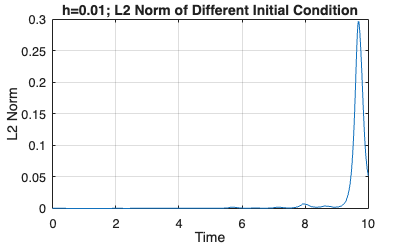

h = 0.01;
[x_ode45_a,y_var_ode45_a,z_ode45_a,t] = lorenz_solver(y0_a, solver, h);
[x_ode45_b,y_var_ode45_b,z_ode45_b,t] = lorenz_solver(y0_b, solver, h);

% Compute L2 norm
diff_norm_ode45 = sqrt((x_ode45_a - x_ode45_b).^2 + (y_var_ode45_a - y_var_ode45_b).^2 + (z_ode45_a - z_ode45_b).^2 );

% Plot L2 norm
figure;
plot(t, diff_norm_ode45);
xlabel('Time');
ylabel('L2 Norm');
title('h=0.01; L2 Norm of Different Initial Condition');
grid on;